# EG-247 Signals and Systems: Lab 01: Elementary Signals

This script file demonstrates the use of the `heaviside` and `dirac` functions. To run the code select the commands in the cells.

## The Unit Step Function

In the notes we define the unit step function as


$${u_0}(t) = \left\{ {\begin{array}{*{20}{c}}{0\quad t < 0}\\{1\quad t > 0}\end{array}} 
\right.$$


In MATLAB the unit step is defined using the `heaviside` function. The command `doc heaviside` will open the documentation for this function in your web browser or a separate documentation window if you're using the desktop MATLAB application.

doc heaviside

Note how the documentation provides a summary of the `heaviside` function but also has interactive code that you can execute.

It's always a good idea to peruse the documentation for any new functions that you encounter. As the documentation pages are just web pages, it's also useful to bookmark the useful ones.

## Using the Symbolic Math Toolbox

The `heaviside` function is part of the [Symbolic Math Toolbox](https://uk.mathworks.com/help/symbolic/index.html) which we will be using a lot in this module. 

We first need to define `t` as a symbol:

syms t;

We can then define and plot the unit step $u_0 \left(t\right)$ by *aliasing* the `heaviside` function with the command:

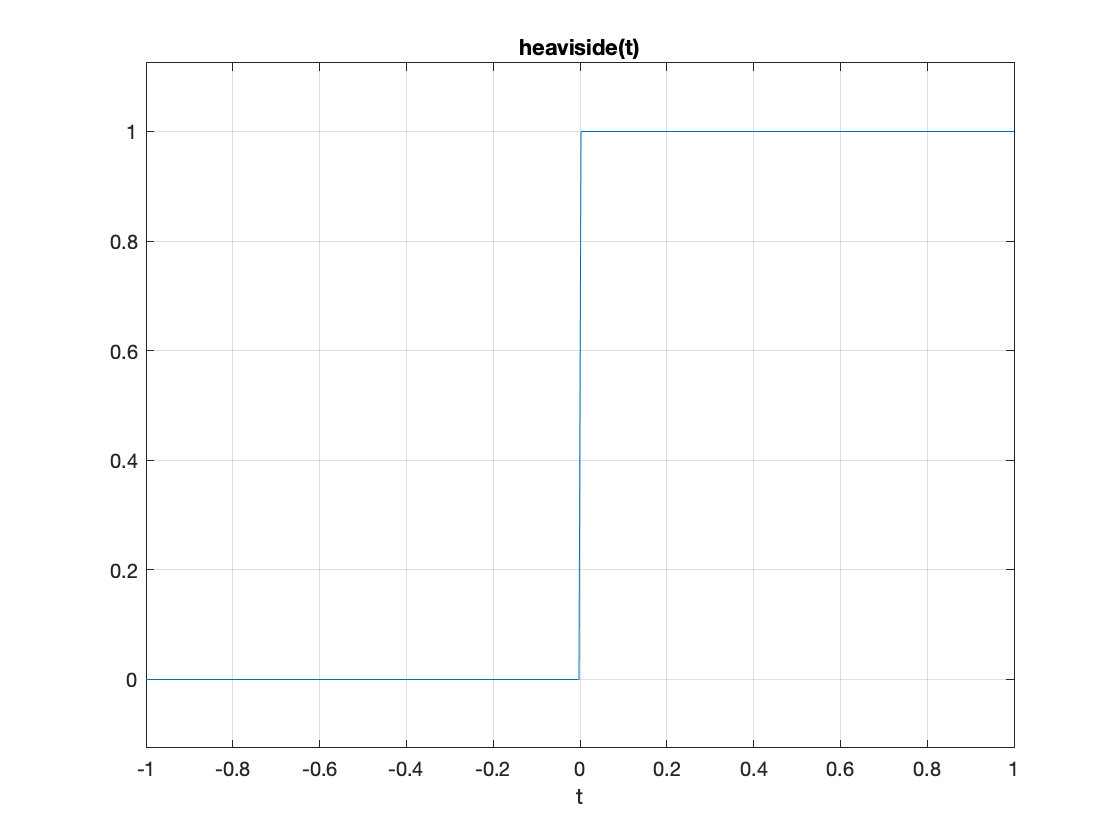

u0(t) = heaviside(t);
ezplot(u0(t),[-1,1]),grid

If we are only interested in the value of the function at a particular instant of time we can pass a number as the argument:

[u0(-1),u0(0),u0(1)]

$$ans = \left(\begin{array}{ccc} 0 & \frac{1}{2} & 1 \end{array}\right)$$

Note that `heaviside(0)` returns the value $1/2$ which is not mathematically correct. As we discussed in class, the unit step function $u_o(t)$ is undefined at $t=0$.

Once you have set things up and defined numerical values of the variables, the basic signal operations work as you'd expect:

A = 2; T = 2;
x0(t) = A * u0(t - T);

And we can plot the signal using the `ezplot` function and label the graph using the `title`, `xlabel` and `ylabel` commands.

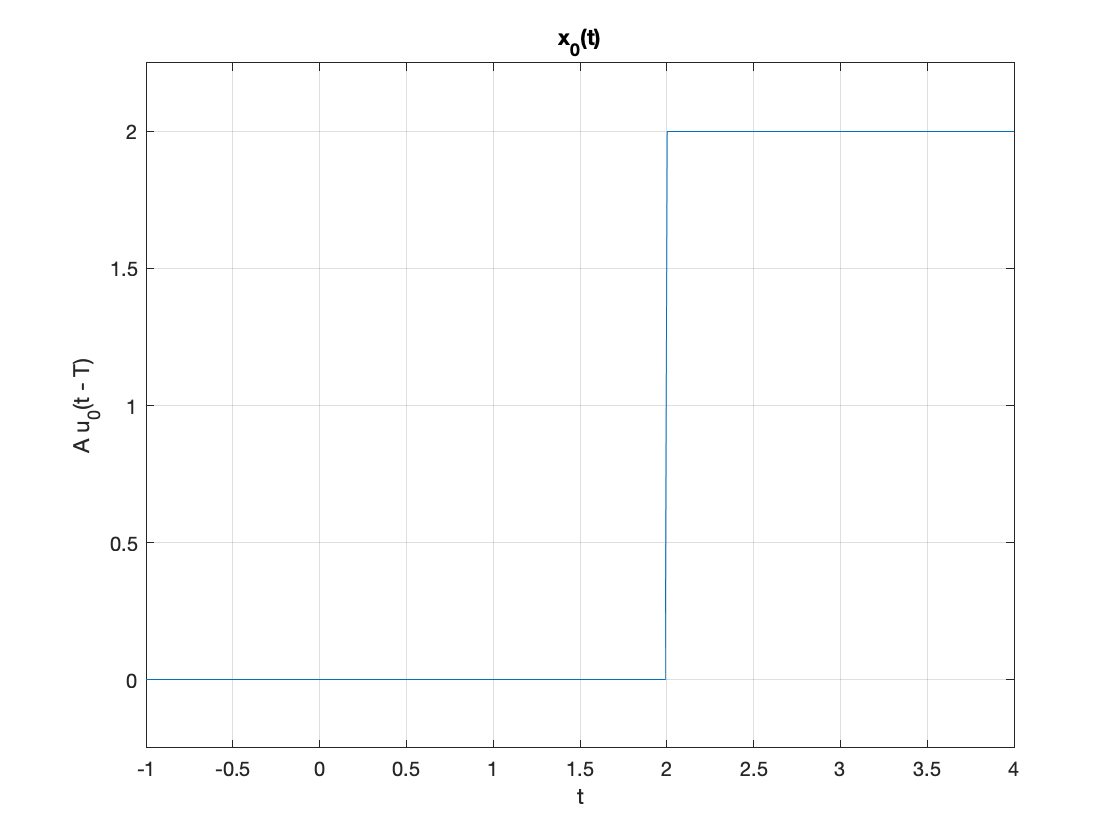

ezplot(x0(t), [-1, 4]),grid
title('x_0(t)'),xlabel('t'),ylabel('A u_0(t - T)')

## Exercise 1

Reproduce Figure 1 (Figure 1.8 from the textbook Karris (page 1-4)) in MATLAB:

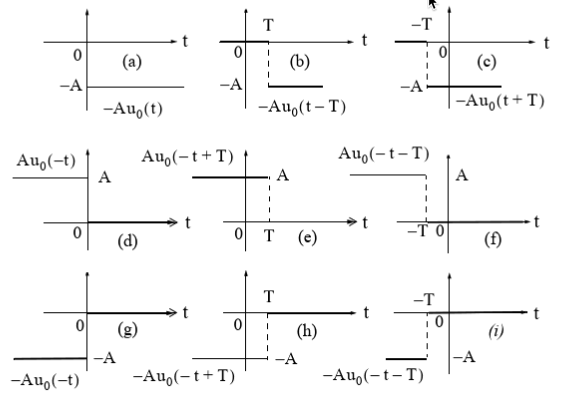**Figure 1 Other forms of the step function**

Use the `heaviside`, `subplot`, and `ezplot` functions to plot each of the following on a 3x3 grid:

- 
$$x_1(t) = -Au_0(t)$$


- 
$$x_2(t) = -Au_0(t-T)$$


- 
$$x_3(t)=-Au_0(t+T)$$


- 
$$x_4(t) = Au_0(-t)$$


- 
$$x_5(t) = Au_0(-t+T)$$


- 
$$x_6(t) = Au_0(-t-T)$$


- 
$$x_7(t) = -Au_0(-t)$$


- 
$$x_8(t)=-Au_0(-t+T)$$


- 
$$x_9(t)=-Au_0(-t-T)$$


We have done the first row of the figure for you.

*Hint*: You will need to adjust the axes of each subplot to ensure that the step function is clearly visible. Compare your results with Figure 1 and tweek your settings until your graph looks right.

### Solution

We'll do the first couple of entries for you.


$$x_1(t) = -Au_0(t)$$


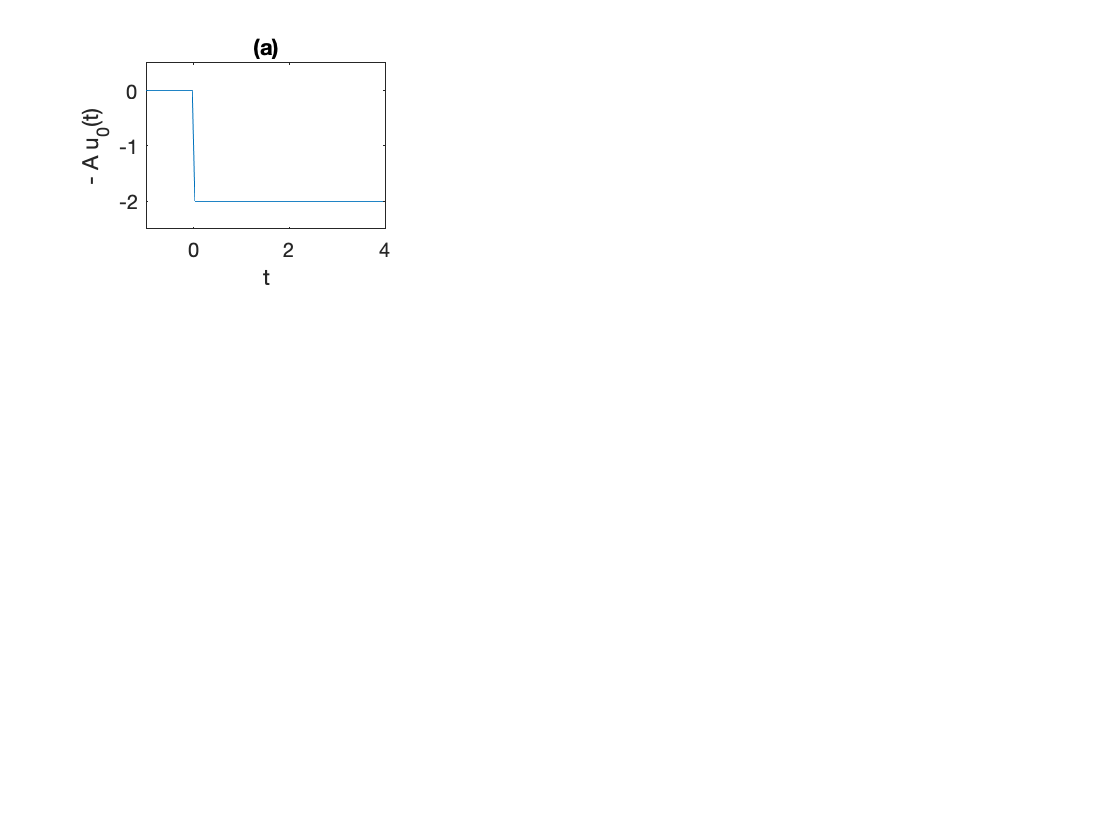

subplot(3,3,1)
x1(t) = - A * u0(t);
ezplot(x1(t), [-1, 4, -2.5, 0.5])
title('(a)'),ylabel('- A u_0(t)'),xlabel('t')


$$x_2(t) = -Au_0(t-T)$$


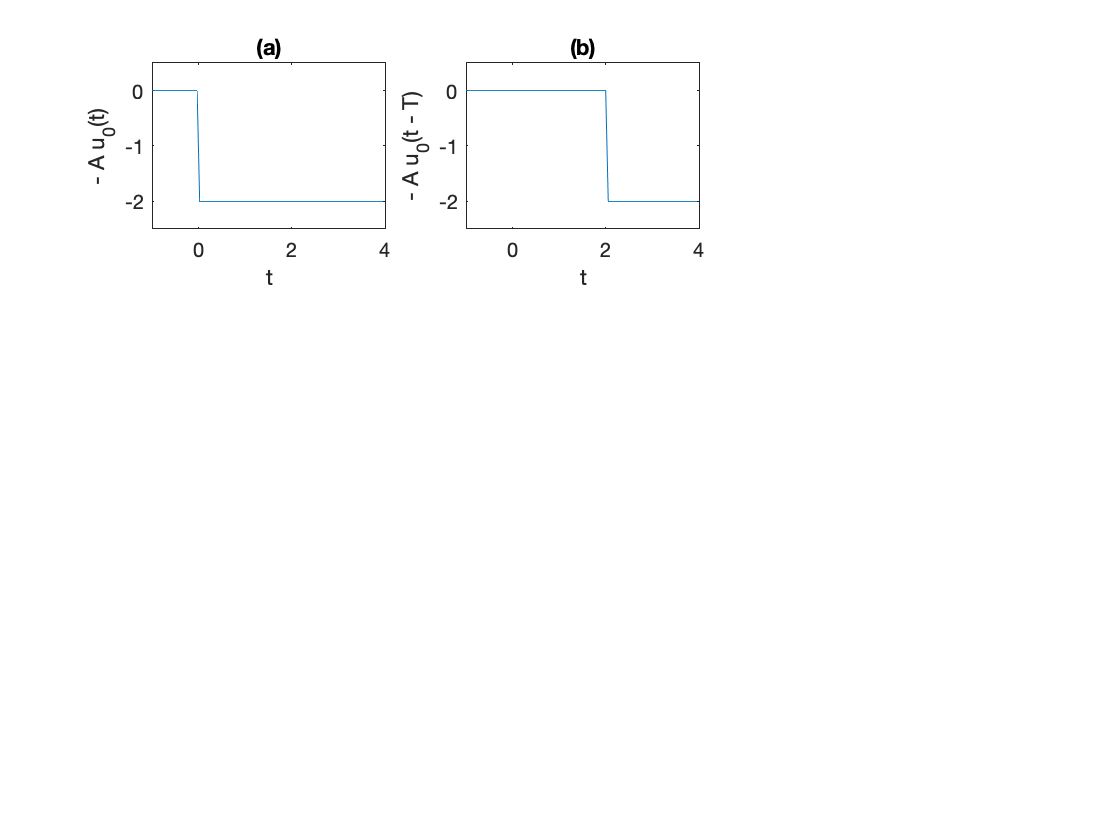

subplot(3,3,2)
x2(t) = - A * u0(t - T);
ezplot(x2(t), [-1, 4, -2.5, 0.5])
title('(b)'),ylabel('- A u_0(t - T)'),xlabel('t')


$$x_3(t)=-Au_0(t+T)$$


Remove the comments below:

% subplot(3,3,3)
% x3(t) = - A * u0(t + T);
% ezplot(x3(t), [-4, 1, -2.5, 0.5])
% title('(c)'),ylabel('- A u_0(t + T)'),xlabel('t')

#### Complete the picture.


$$x_4(t) = Au_0(-t)$$


subplot(3,3,4)

Your code goes here for x`4(t)` to `x9(t).`

% Clear figure before moving on
clf

## Part 2

Use the `heaviside` and `ezplot` function to show that $u_0(t) - u_0(t - 1)$ represents the rectangular pulse shown in Figure 1.9 (a) in the textbook.

## Part 3

Use the `heaviside` and `ezplot` functions to validate equations 1.13, 1.14, 1.17 and 1.18 in the textbook.

## The Ramp Function

The integral of the **unit step** function is the **ramp function**


$$u_1(t) = \int_{-\infty}^{t} u_0(\tau)d\tau$$


Gives


$${u_1}(t) = \left\{ {\begin{array}{*{20}{c}}{0\quad t < 0}\\{t\quad t > 0}\end{array}} 
\right. = t{u_0}(t)$$


To verify this result:

syms tau
int(heaviside(tau),-inf, t)

$$ans = \frac{t\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}$$

Plot the ramp function

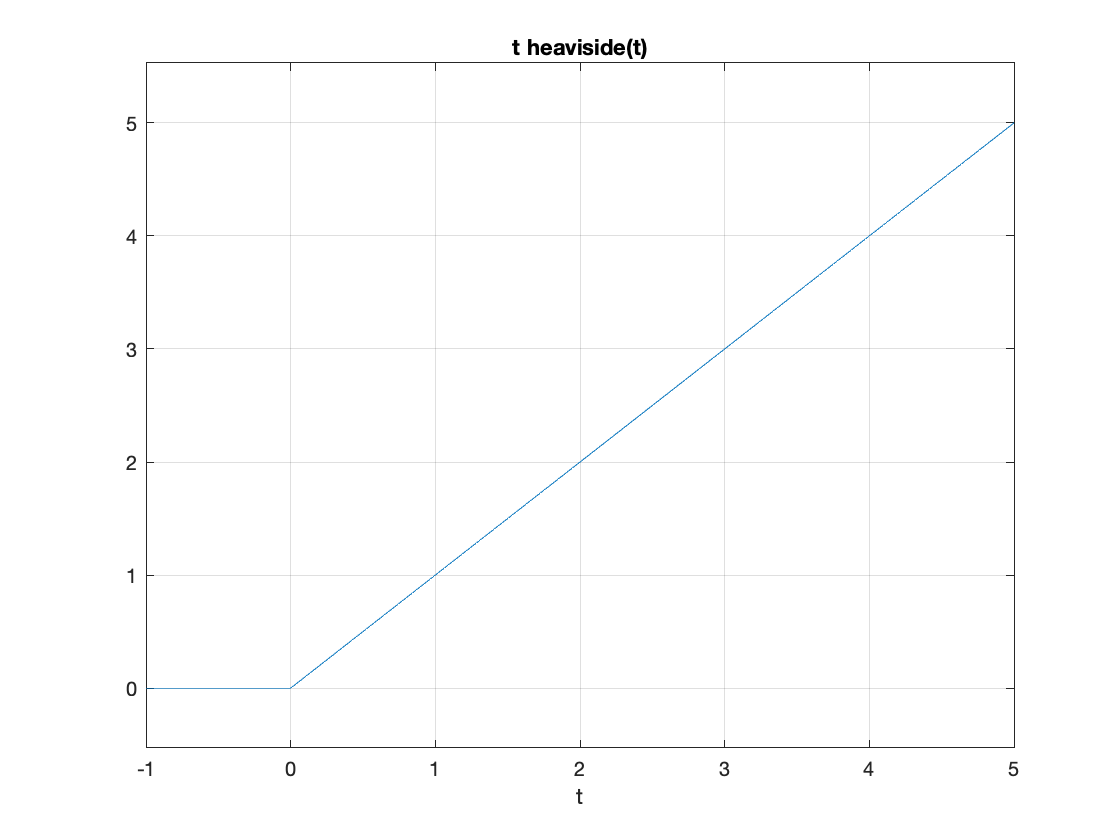

ezplot(t * heaviside(t), [-1,5]), grid

## Part 4

Use `ezplot` to plot $u_2(t)$ and $u_3(t)$ computed as defined on Page 1-10 of the textbook.

## The Dirac Delta Function

$\delta(t)$ is the derivative of $u_0(t)$

diff(heaviside(t),t)

$$ans = \delta (t)$$

It's not easy to plot the dirac delta function. We have to cheat a little by using a stem plot:

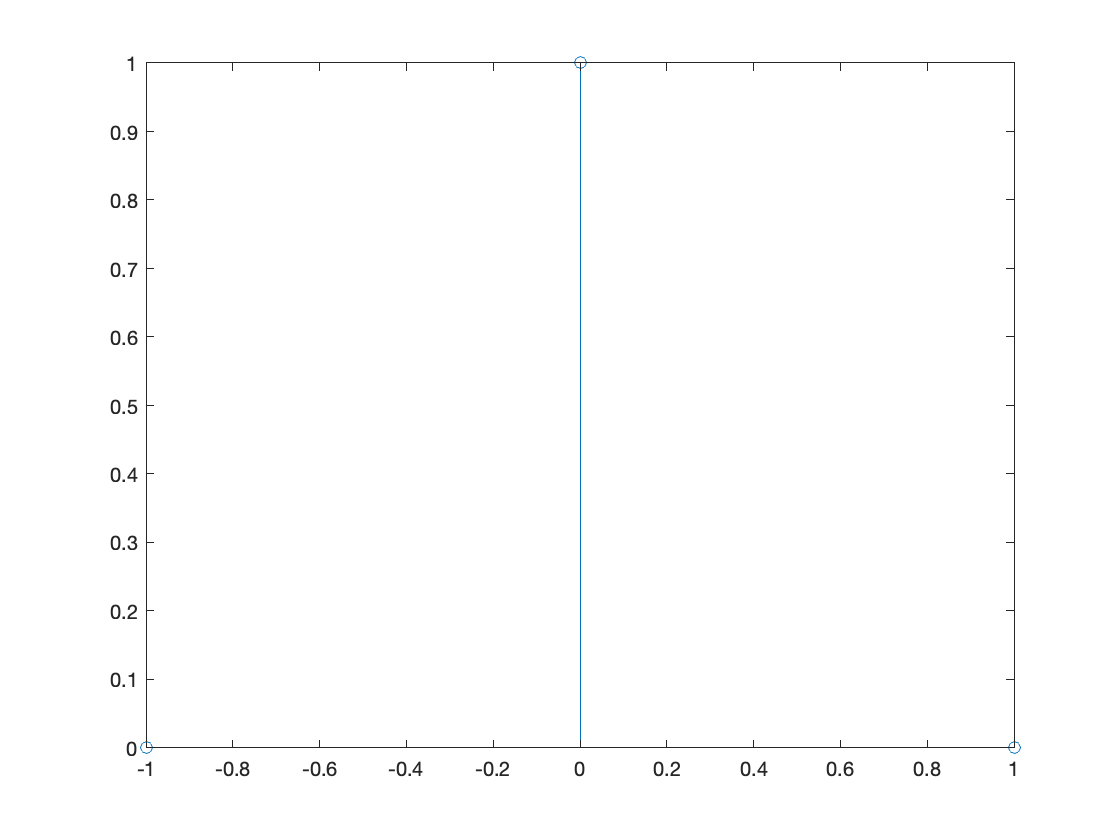

td = [-1,0,1]; delta = [0,1,0];
stem(td,delta)

MATLAB has this function and its derivatives built-in

dirac(t)

$$ans = \delta (t)$$

% $\delta^'(t)$
dirac(1,t)

$$ans = \delta^{\prime }(t)$$

% $delta^{''}(t)$
dirac(2,t)

$$ans = \delta^{\prime \prime }(t)$$

## Part 5

Use MATLAB to solve Examples 1.8 and 1.9 from the textbook. You may not get the results you expect so if this is the case, just comment on the result. 

Don't Forget to Save Your Work!